# Signal Model

clc;
clear;

N = 500; % Number of symbols in s
P = 4;
sigma = 0;

symbols_list = [-1/sqrt(2), 1/sqrt(2), -1i/sqrt(2), 1i/sqrt(2)];
idx = randi([1, 4], 1, N);
s = symbols_list(idx);

x = gendata_conv(s, P, N, sigma);

X = zeros(2*P, N-1);
for i = 1:N-1
    X(:, i) = x((i-1)*P+1:(i+1)*P);
end

rank_X = rank(X);

% Double P
x_2P = gendata_conv(s, 2*P, N, sigma);
X_2P = zeros(2*2*P, N-1);
for i = 1:N-1
    X_2P(:, i) = x_2P((i-1)*2*P+1:(i+1)*2*P);
end

rank_X_2P = rank(X_2P);

## Zero-forcing and Wiener Equalizer

N = 500; % Number of symbols in s
P = 4;
sigma = 0.5;

x = gendata_conv(s, P, N, sigma);

X = zeros(2*P, N-1);
for i = 1:N-1
    X(:, i) = x((i-1)*P+1:(i+1)*P);
end

h = ones(P, 1);
for i = 1:P
    if ((i-1)/P >= 0.25)&&((i-1)/P < 0.5) || ((i-1)/P >= 0.75)&&((i-1)/P < 1)
        h(i) = -1;
    else
        h(i) = h(i);
    end
end

H = [zeros(P, 1), h; h, zeros(P, 1)];
[m, ~] = size(H);
I = eye(m);

W_zf = pinverse(H, rank(H))';
W_wn = (H'*inv(H*H' + sigma^2*I))';

S_zf = W_zf'*X;
S_wn = W_wn'*X;

Real_zf = real(S_zf);
Imag_zf = imag(S_zf);

Real_wn = real(S_wn);
Imag_wn = imag(S_wn);

real_s = real(s);
imag_s = imag(s);

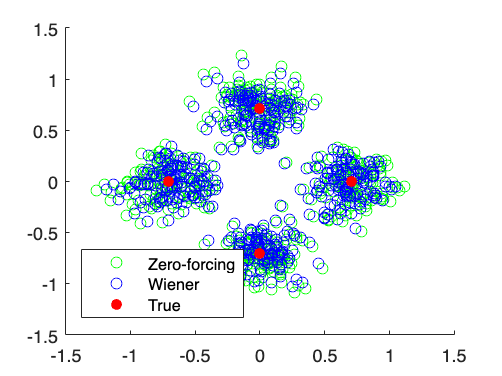

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Observe the two different shifts %
%  No need to run this every time  %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

scatter(Real_zf(1, :), Imag_zf(1, :), 'green');

hold on
scatter(Real_wn(1, :), Imag_wn(1, :), 'blue');

scatter(real_s, imag_s, 'red', 'filled');

hold off
legend({'Zero-forcing','Wiener','True'},'location','best')

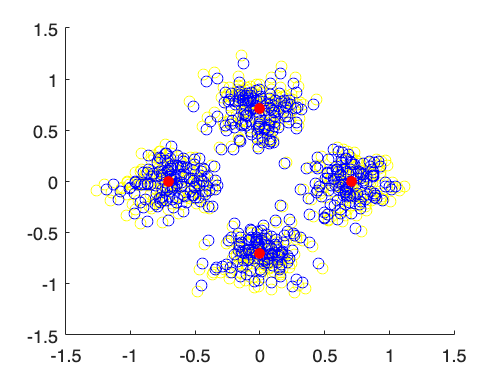


scatter(Real_zf(2, :), Imag_zf(2, :), 'yellow');
hold on
scatter(Real_wn(2, :), Imag_wn(2, :), 'blue');
scatter(real_s, imag_s, 'red', 'filled');
hold off

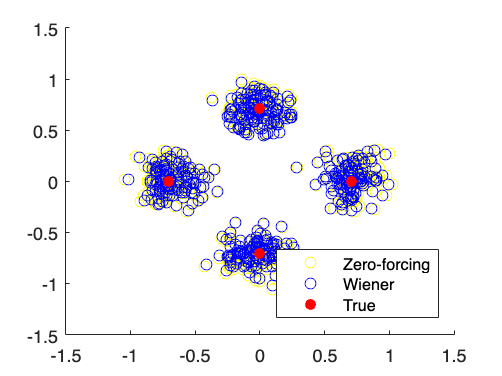

% Double P
N = 500; % Number of symbols in s
P = 8;
sigma = 0.5;

x = gendata_conv(s, P, N, sigma);

X = zeros(2*P, N-1);
for i = 1:N-1
    X(:, i) = x((i-1)*P+1:(i+1)*P);
end

h = ones(P, 1);
for i = 1:P
    if ((i-1)/P >= 0.25)&&((i-1)/P < 0.5) || ((i-1)/P >= 0.75)&&((i-1)/P < 1)
        h(i) = -1;
    else
        h(i) = h(i);
    end
end

H = [zeros(P, 1), h; h, zeros(P, 1)];
[m, ~] = size(H);
I = eye(m);

W_zf = pinverse(H, rank(H))';
W_wn = (H'*inv(H*H' + sigma^2*I))';

S_zf = W_zf'*X;
S_wn = W_wn'*X;

Real_zf = real(S_zf);
Imag_zf = imag(S_zf);

Real_wn = real(S_wn);
Imag_wn = imag(S_wn);

real_s = real(s);
imag_s = imag(s);

scatter(Real_zf(1, :), Imag_zf(1, :), 'yellow');
hold on
scatter(Real_wn(1, :), Imag_wn(1, :), 'blue');
scatter(real_s, imag_s, 'red', 'filled');
axis([-1.5 1.5 -1.5 1.5])
hold off
legend({'Zero-forcing','Wiener','True'},'location','best')

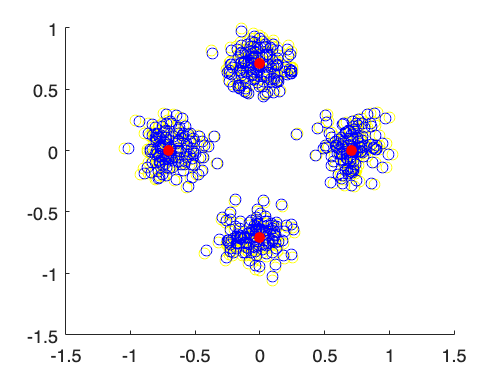

scatter(Real_zf(2, :), Imag_zf(2, :), 'yellow');
hold on
scatter(Real_wn(2, :), Imag_wn(2, :), 'blue');
scatter(real_s, imag_s, 'red', 'filled');
hold off